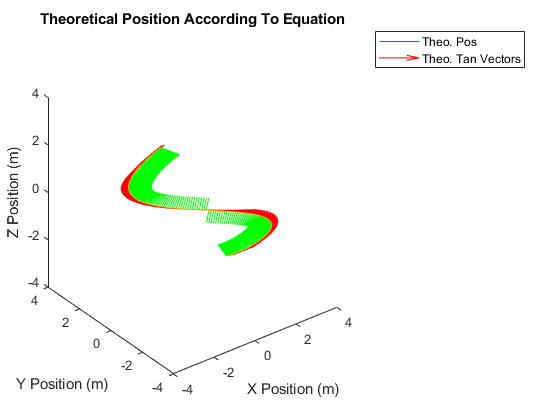

clc, clear all;
syms R u r t;

d=.235; %wheelbase distance
beta=.334; %multiplying constant 
steps=200; %number of parametric steps

u=beta*t; %define u in terms of t (time)

%define the parametric in terms of u
%r(u) = 4[0.3960cos(2.65(u + 1.4))i - 0.99sin(u + 1.4)j]. (u E [0,3.2])
ri=R*0.3960*cos(2.65*(u + 1.4));
rj=-R*0.99*sin(u + 1.4);
rk=0*u;
r=[ri,rj,rk];

%mathematical assumptions
assume(R,{'real','positive'});
assume(t,{'real','positive'});

%get T hat
dr=diff(r,t);
T_hat_ugly=dr./norm(dr);
T_hat=simplify(T_hat_ugly);

%get N hat
dT_hat=diff(T_hat,t);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat);

Omega=cross(T_hat,dT_hat); %define the angular velocity
LS = norm(dr); %define the linear speed
 
R_num = 4; %define a specific radius
t_num = linspace(0,3.2/beta,steps); %define a set of evenly spaced points between 0 and 3.2 (the upper bound) times beta

% plot figure 1
figure(1)
for n=1:length(t_num)
    %convert symbolic expressions to doubles
    r_num(n,:)=double(subs(r,[R, t],[R_num, t_num(n)])); %calculate instantaneous position
    T_hat_num(n,:)=double(subs(T_hat,[R, t],[R_num, t_num(n)])); %calculate instantaneous unit tangent vector
    N_hat_num(n,:)=double(subs(N_hat,[R, t],[R_num, t_num(n)])); %calculate instantaneous unit normal vector
    
    Omega_num(n,:)=double(subs(Omega,[R, t],[R_num, t_num(n)])); %calculate instantaneous angular velocity
    LS_num(n,:)=double(subs(LS,[R, t],[R_num, t_num(n)])); %calculate instantaneous linear speed
    
    plot3(r_num(:,1),r_num(:,2),r_num(:,3)), axis([-4 4 -4 4 -4 4]),hold on % plot the entire curve
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),T_hat_num(n,1),T_hat_num(n,2),T_hat_num(n,3),'r'); %plot the unit tangent vectors
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),N_hat_num(n,1),N_hat_num(n,2),N_hat_num(n,3),'g'); %plot the unit normal vectors
    hold on; %dont clear
end
xlabel('X Position (m)');
ylabel('Y Position (m)');
zlabel('Z Position (m)');
legend('Theo. Pos','Theo. Tan Vectors');
title('Theoretical Position According To Equation');
hold off;


vL_T=LS_num-Omega_num(:,3).*(.235/2); %theoretical left wheel velocity
vR_T=LS_num+Omega_num(:,3).*(.235/2); %theoretical right wheel velocity

%{
IF YOU ARE RUNNING THINGS FOR THE FIRST TIME COMMENT OUT
EVERTHING AFTER THIS POINT WITH A MULTI-LINE COMMENT LIKE THIS.
RUN 'collectDataset_sim.m' AND COLLECT ENCODER DATA FROM
THE SCRIPT 'BridgeOfDoomQEA2020.m'.

ONCE COMPLETED YOU CAN UNCOMMENT THE SECOND HALF AND CHANGE THE
FILENAME FOR THE NAME YOU SAVED THE TRIAL DATA TO.
%}

%%%%  RESULTS & ANALYSIS  %%%%

load BODtrial.mat % load collected data

%setting up variables for left and right vel
s=dataset(:,1),s=s(55:end,:); %s is used as a replacement for t to not overwrite the previous sym with the name 't'

s =     0.0870
    0.1870
    0.2880
    0.3870
    0.4890
    0.6540
    0.6870
    0.8360
    1.0900
    1.3730


rL_E=dataset(:,2),rL_E=rL_E(55:end,:);

rL_E =   611.3810
  611.3810
  611.3810
  611.3810
  611.3810
  611.3810
  611.3810
  611.3810
  611.3810
  611.3810


rR_E=dataset(:,3),rR_E=rR_E(55:end,:);

rR_E =   665.4131
  665.4131
  665.4131
  665.4131
  665.4131
  665.4131
  665.4131
  665.4131
  665.4131
  665.4131


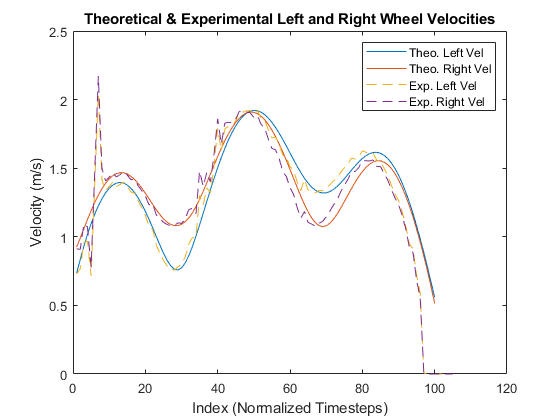

dt=diff(s);
dL_E=diff(rL_E);
dR_E=diff(rR_E);
vL_E=dL_E./dt;
vR_E=dR_E./dt;

%plot figure 2
figure(2)
plot(vL_T(2:2:end,:),'-'),hold on; %(2:2:end,:) due to doubling of data at each step from linspace
plot(vR_T(2:2:end,:),'-'),hold on;
plot(vL_E,'--'),hold on;
plot(vR_E,'--');
xlabel('Index (Normalized Timesteps)');
ylabel('Velocity (m/s)');
legend('Theo. Left Vel','Theo. Right Vel','Exp. Left Vel','Exp. Right Vel');
title('Theoretical & Experimental Left and Right Wheel Velocities');
hold off;

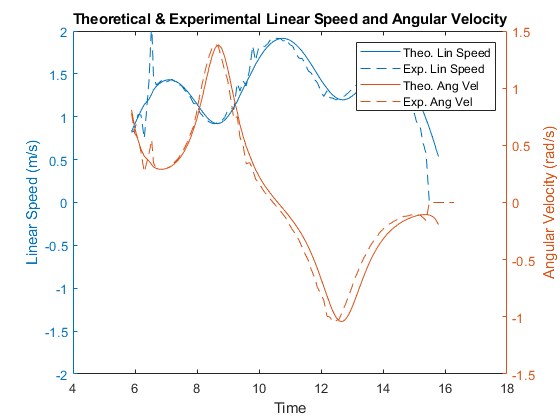


%setting up variables for linear speed and angular velocity
v_E=(vL_E+vR_E)./2;
v_T=(vL_T+vR_T)./2;
omega_E=(vR_E-vL_E)./d;
omega_T=(vR_T-vL_T)./d;

%plot figure 3
figure(3)
yyaxis left;
plot(s(1:end-6),v_T(2:2:end,:),'-'),hold on;
plot(s(1:end-1),v_E,'--'),hold on;
ylim([-2,2]); %limits of wheel velocity
xlabel('Time');
ylabel('Linear Speed (m/s)');
yyaxis right;
plot(s(1:end-6),omega_T(2:2:end,:),'-'),hold on;
plot(s(1:end-1),omega_E,'--'),hold on;
ylabel('Angular Velocity (rad/s)');
legend('Theo. Lin Speed','Exp. Lin Speed','Theo. Ang Vel','Exp. Ang Vel');
title('Theoretical & Experimental Linear Speed and Angular Velocity');
hold off;

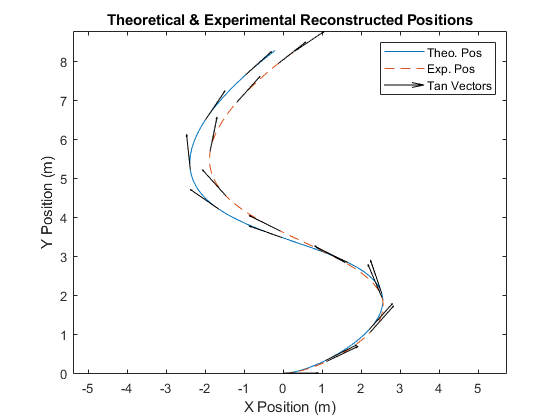


% setting up variables for path regeneration
r_E=zeros(length(s),2);
theta_E=zeros(length(s),1);
for n=1:length(dt) 
    r_E(n+1,1)=r_E(n,1)+v_E(n)*cos(theta_E(n))*dt(n);
    r_E(n+1,2)=r_E(n,2)+v_E(n)*sin(theta_E(n))*dt(n);
    theta_E(n+1)=theta_E(n)+omega_E(n)*dt(n);
end

r_T=zeros(200,2);
theta_T=zeros(200,1);
for n=1:199
    r_T(n+1,1)=r_T(n,1)+v_T(n)*cos(theta_T(n))*.05; %theoretical steps are consistent
    r_T(n+1,2)=r_T(n,2)+v_T(n)*sin(theta_T(n))*.05;
    theta_T(n+1)=theta_T(n)+omega_T(n)*.05;
end

% plot figure 4
figure(4)
plot(r_T(:,1),r_T(:,2),'-'),hold on;
plot(r_E(:,1),r_E(:,2),'--'),hold on;
for k=1:20:length(r_T)
    quiver(r_T(k,1),r_T(k,2),cos(theta_T(k)),sin(theta_T(k)),'color','k'); % take theoretical xy coordinate and xy vector components
end
for k=1:10:length(r_E)
    quiver(r_E(k,1),r_E(k,2),cos(theta_E(k)),sin(theta_E(k)),'color','k'); % take experimental xy coordinate and xy vector components
end
axis equal;
legend('Theo. Pos','Exp. Pos','Tan Vectors');
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Theoretical & Experimental Reconstructed Positions');
hold off;